clear
close all
clc



%% load Image
[X,cmap] = imread('Test.png')

X = 655×875×3 uint8 array
X(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255  


cmap =

     []



X1 = X(:,:,1)

X1 = 655×875 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   25



%% Enter the Axes
Axes_input = inputdlg({'x1','x2','y1', 'y2'},...
    'Enter the numerical value of the coordinates you are going to click on',...
    [1 100; 1 100; 1 100 ; 1 100])

Axes_input = 4×1 cell array
    {'0' }
    {'10'}
    {'0' }
    {'35'}


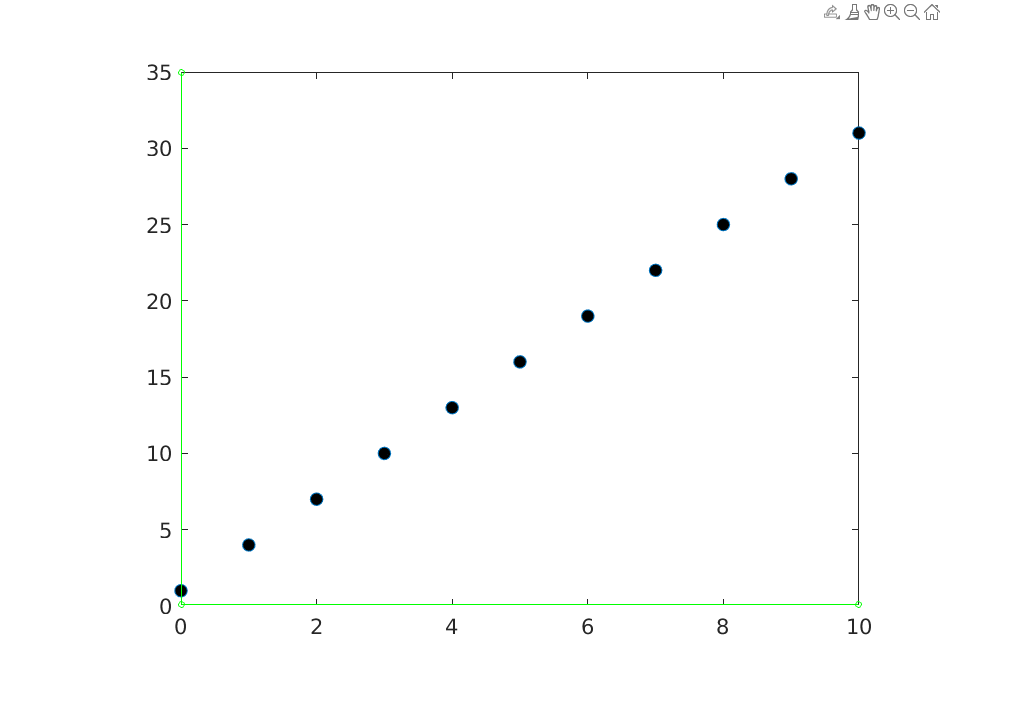

Axes_click =   115.0000  792.0000  115.0000  115.0000
  582.0000  582.0000  582.0000   50.0000



Axes_click = readPoints('Test.png', 4)



%% Make four clicks around the shape of the data point

message = 'mark four clicks around the data point';
title = 'Mark shape';
uiwait(msgbox(message, title))

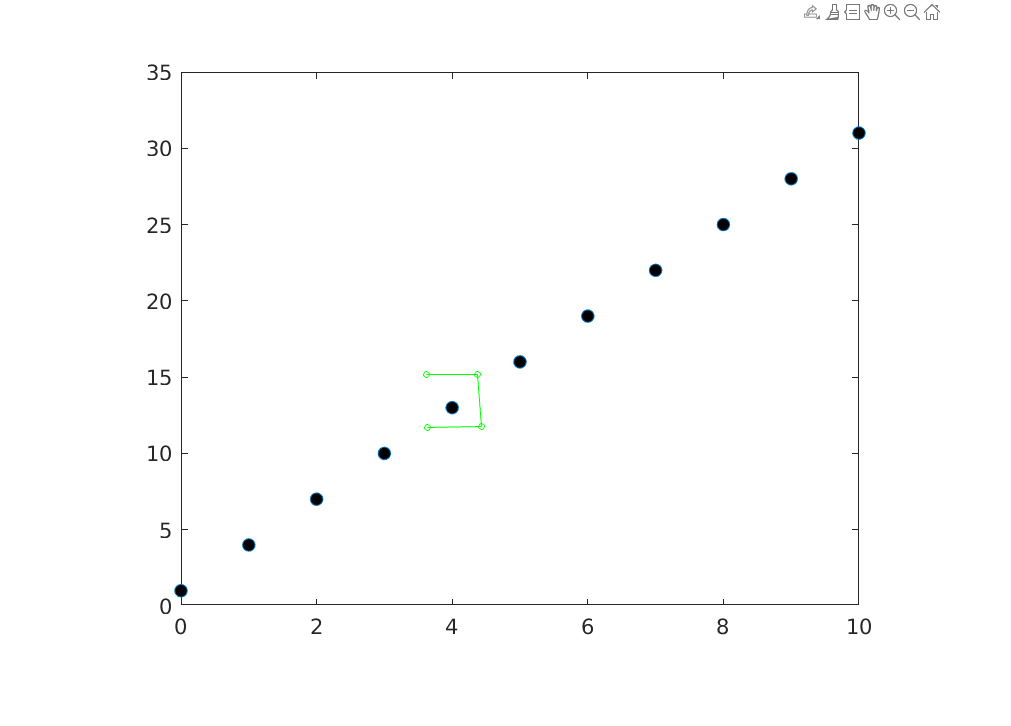

Shape_click =    360   411   415   361
   352   352   404   405


Shape_click = readPoints('Test.png', 4)


left = ceil(min(Shape_click(1,:)))

left = 360

lower = ceil(max(Shape_click(2,:)))

lower = 405

right = ceil(max(Shape_click(1,:)))

right = 415

upper = ceil(min(Shape_click(2,:)))

upper = 352



%% Show the shape of the data point
shape = X(upper:lower, left:right,:);
shape1 = shape(:,:,1)

shape1 = 54×56 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   

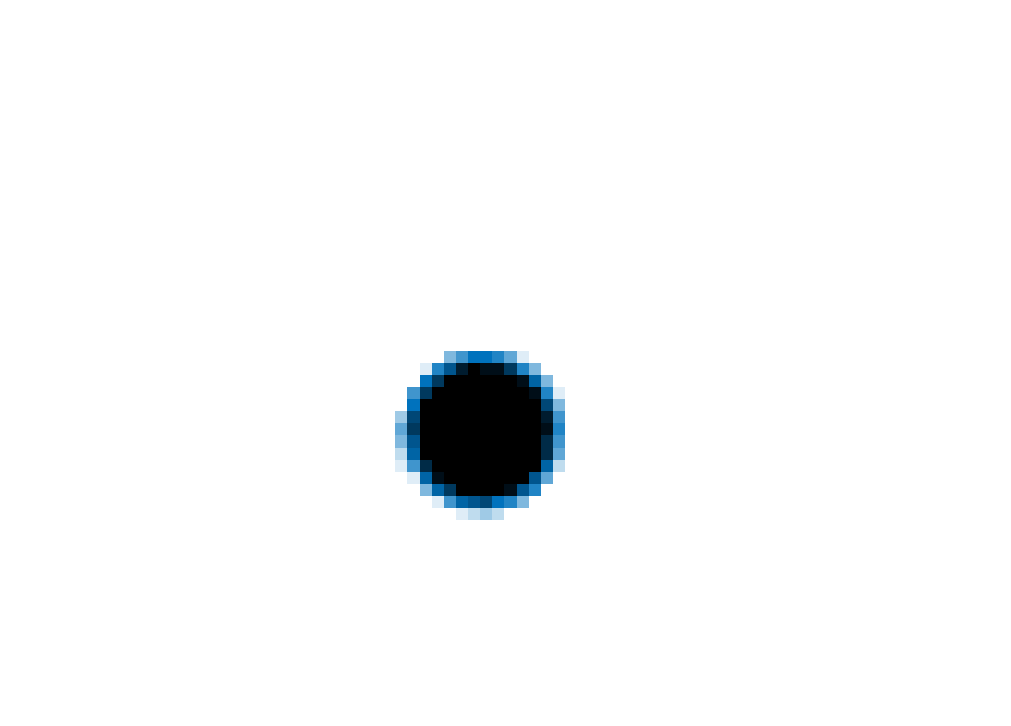

imshow(shape,cmap);

%% Apply sliding mask
% load('Clicks.mat')

sizeShape = size(shape)

sizeShape =     54    56     3



% What are possible centers
vert = ceil(sizeShape(1)/2)

vert = 27

hor = ceil(sizeShape(2)/2)

hor = 28


% Potential upper left
Vec = 1: numel(X(:,:,1))

Vec =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


PointsMat = zeros(size(X(:,:,1)))

PointsMat =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

PointsMat(1:end) = Vec

PointsMat =            1         656        1311        1966        2621        3276        3931        4586        5241        5896        6551        7206        7861        8516        9171        9826       10481       11136       11791       12446       13101       13756       14411       15066       15721       16376       17031       17686       18341       18996       19651       20306       20961       21616       22271       22926       23581       24236       24891       25546       26201       26856       27511       28166       28821       29476       30131       30786       31441       32096
           2         657        1312        1967        2622        3277        3932        4587        5242        5897        6552        7207        7862        8517        9172        9827       10482       11137       11792       12447       13102       13757       14412       15067       15722       16377       17032       17687       18342       18997       19652       20307   


PotentialUL = PointsMat(1:end-sizeShape(1), 1:end-sizeShape(2))

PotentialUL =            1         656        1311        1966        2621        3276        3931        4586        5241        5896        6551        7206        7861        8516        9171        9826       10481       11136       11791       12446       13101       13756       14411       15066       15721       16376       17031       17686       18341       18996       19651       20306       20961       21616       22271       22926       23581       24236       24891       25546       26201       26856       27511       28166       28821       29476       30131       30786       31441       32096
           2         657        1312        1967        2622        3277        3932        4587        5242        5897        6552        7207        7862        8517        9172        9827       10482       11137       11792       12447       13102       13757       14412       15067       15722       16377       17032       17687       18342       18997       19652       20307 


X1(X1==0) = 1

X1 = 655×875 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   25

X1(X1~=1) = 0

X1 = 655×875 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

shape1(shape1==0) = 1

shape1 = 54×56 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   

shape1(shape1~=1) = 0

shape1 = 54×56 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


for i = 1:size(PotentialUL,1)
    for j = 1 : size(PotentialUL,2)
   
        FilterResult(i,j) = sum(shape1(:,:).*X1(i:i+sizeShape(1)-1,j:j+sizeShape(2)-1),'all');
        
    end
end

%% Welches Upper-left gehört zu welchem Mittelpunkt? 


%% Welche Koordinaten haben die Mittelpunkte?




%% Functions

function pts = readPoints(image, n)
%readPoints   Read manually-defined points from image
%   POINTS = READPOINTS(IMAGE) displays the image in the current figure,
%   then records the position of each click of button 1 of the mouse in the
%   figure, and stops when another button is clicked. The track of points
%   is drawn as it goes along. The result is a 2 x NPOINTS matrix; each
%   column is [X; Y] for one point.
%
%   POINTS = READPOINTS(IMAGE, N) reads up to N points only.
if nargin < 2
    n = Inf;
    pts = zeros(2, 0);
else
    pts = zeros(2, n);
end
imshow(image);     % display image
xold = 0;
yold = 0;
k = 0;
hold on;           % and keep it there while we plot
while 1
    [xi, yi, but] = ginput(1);      % get a point
    if ~isequal(but, 1)             % stop if not button 1
        break
    end
    k = k + 1;
    pts(1,k) = xi;
    pts(2,k) = yi;
    if xold
        plot([xold xi], [yold yi], 'go-');  % draw as we go
    else
        plot(xi, yi, 'go');         % first point on its own
    end
    if isequal(k, n)
        break
    end
    xold = xi;
    yold = yi;
end
hold off;
if k < size(pts,2)
    pts = pts(:, 1:k);
end
end